# Quiz 3

Kathryn Atherton

ABE 30100

March 4, 2019

Problem

**Part A**

% Variables
time = [0, 1, 2, 3, 4, 5, 6, 7, 8, 9, 10];
A = [100, 86.0779764, 74.08182207, 63.76281516, 54.88116361, 47.23665527, 40.65696597,...
    34.99377491, 30.11942119, 25.92402606, 22.31301601];

fprintf('Spline Equations:')

Spline Equations:

spline = cubic_spline(time,A);

Valid from x = 0.0000 to 1.0000

$$f = 0.41809\,x^{3}-14.34\,x+100.0$$

Valid from x = 1.0000 to 2.0000

$$f = 1.2543\,{\left(x-1.0\right)}^{2}-13.086\,x-0.16459\,{\left(x-1.0\right)}^{3}+99.164$$

Valid from x = 2.0000 to 3.0000

$$f = 0.76051\,{\left(x-2.0\right)}^{2}-11.071\,x-0.0084603\,{\left(x-2.0\right)}^{3}+96.224$$

Valid from x = 3.0000 to 4.0000

$$f = 0.73513\,{\left(x-3.0\right)}^{2}-9.5754\,x-0.041362\,{\left(x-3.0\right)}^{3}+92.489$$

Valid from x = 4.0000 to 5.0000

$$f = 0.61104\,{\left(x-4.0\right)}^{2}-8.2292\,x-0.026302\,{\left(x-4.0\right)}^{3}+87.798$$

Valid from x = 5.0000 to 6.0000

$$f = 0.53214\,{\left(x-5.0\right)}^{2}-7.0861\,x-0.025754\,{\left(x-5.0\right)}^{3}+82.667$$

Valid from x = 6.0000 to 7.0000

$$f = 0.45487\,{\left(x-6.0\right)}^{2}-6.0991\,x-0.019005\,{\left(x-6.0\right)}^{3}+77.251$$

Valid from x = 7.0000 to 8.0000

$$f = 0.39786\,{\left(x-7.0\right)}^{2}-5.2463\,x-0.025889\,{\left(x-7.0\right)}^{3}+71.718$$

Valid from x = 8.0000 to 9.0000

$$f = 0.32019\,{\left(x-8.0\right)}^{2}-4.5283\,x+0.012682\,{\left(x-8.0\right)}^{3}+66.346$$

Valid from x = 9.0000 to 10.0000

$$f = 0.35824\,{\left(x-9.0\right)}^{2}-3.8498\,x-0.11941\,{\left(x-9.0\right)}^{3}+60.573$$

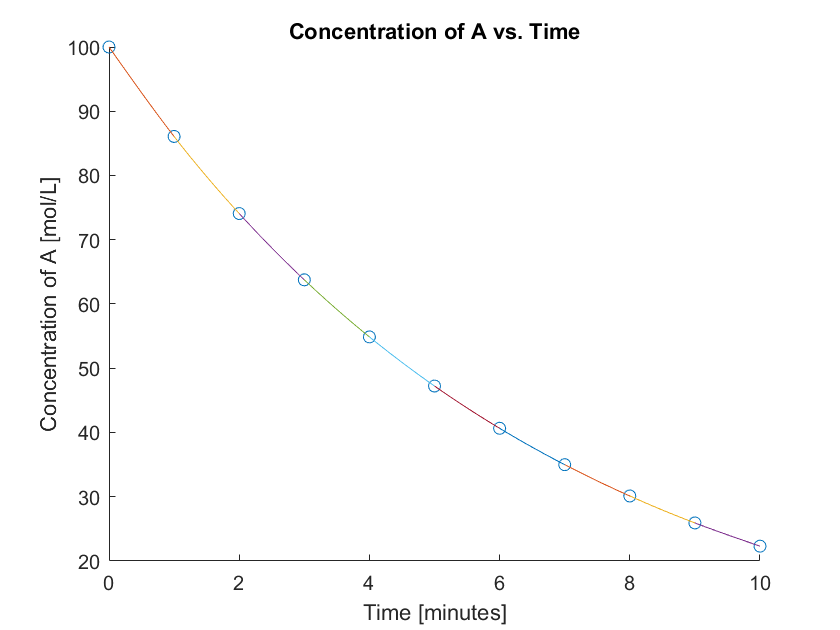

title('Concentration of A vs. Time')
xlabel('Time [minutes]')
ylabel('Concentration of A [mol/L]')

**Part B**

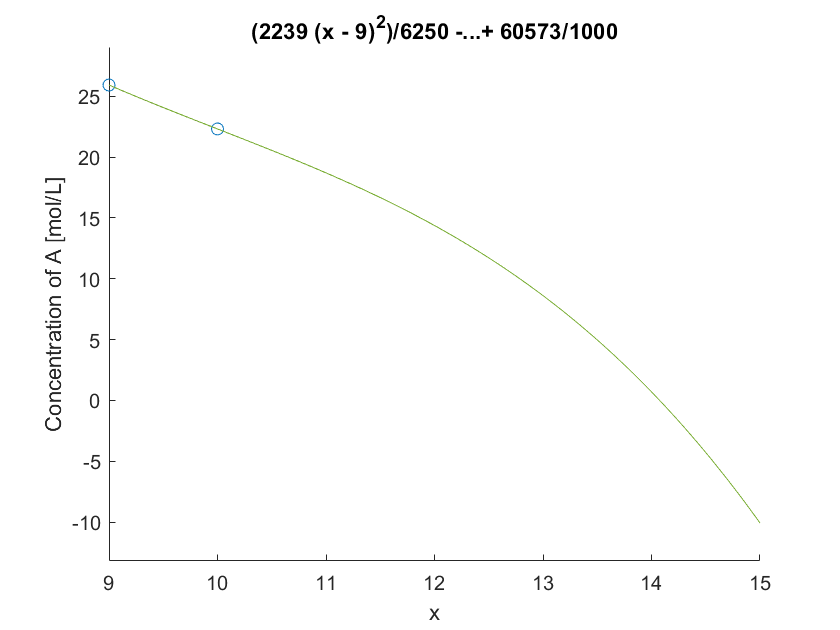

f = 0.35824 * (x - 9)^2 - 3.8498 * x - 0.11941 * (x - 9)^3 + 60.573;
ezplot(f,[9,15])


f = f-5;
x1 = 10;
error_tol = 0.001;

[x_root, i] = newton_raphson(f, x1, error_tol)

x_root = 13.4967

i = 4

x_root = x_root / 2

x_root = 6.7483

**Functions**

function S = cubic_spline(x1, y)
m = length(x1);
n = length(y);

if m ~= n
    error('Error: x and y have different dimensions.');
elseif m < 3
    error('Error: not enough points to create a cubic spline.');
else
    scatter(x1,y);
    hold on;
    [A, B, C, D] = spline_coeff(x1,y); 
    S = zeros(m, 1);
    for i = 1:m-1
        a = double(A(i));
        b = double(B(i));
        c = double(C(i));
        d = double(D(i));
        digits(5)
        syms x
        fprintf('Valid from x = %.4f to %.4f', x1(i), x1(i + 1))
        f = vpa(a) + (vpa(b) * (x - vpa(x1(i)))) + (vpa(c) * ((x - vpa(x1(i))) ^ 2)) + ...
            (vpa(d) * ((x - vpa(x1(i))) ^ 3))
        vals = x1(i):0.01:x1(i+1);
        x = vals;
        plot(vals, subs(f));
        hold on;
    end
end
end

function H = h_matrix(x)
n = length(x);
H = zeros(n,n);
H(1,1) = 1;
H(n,n) = 1;
for i = 2:n-1
    for j = 1:n
        if j == i
            H(i, j) = double(2 * ((x(i) - x(i - 1)) + (x(i + 1) - x(i))));
            H(i, j - 1) = double(x(i) - x(i - 1));
            H(i, j + 1) = double(x(i + 1) - x(i));
        end
    end
end
end

function C = k_matrix(x, y)
m = length(x);
n = length(y);
if m ~= n
    error("Error: x and y have different dimensions.");
else
    K = zeros(m,1);
    for i = 2:m-1
        h1 = double(x(i + 1) - x(i));
        h0 = double(x(i) - x(i - 1));
        a2 = double(y(i + 1));
        a1 = double(y(i));
        a0 = double(y(i - 1));
        K(i,1) = double(((3 * (a2 - a1)) / h1) - ((3 * (a1 - a0)) / h0)); 
    end
    H = h_matrix(x);
    C = H\K;
end
end

function [A, B, C, D] = spline_coeff(x, y)
m = length(x);
n = length(y);
if m ~= n
    error('Error: x and y have different dimensions.');
else
    B = zeros(length(y)-1,1);
    D = B;
    C = k_matrix(x,y);
    A = y;
    for i = 1:m-1
        h = (x(i + 1) - x(i));
        B(i,1) = double(((A(i + 1) - A(i)) / h) - (((C(i + 1) + 2 * C(i)) * h) / 3));
        D(i,1) = double((C(i + 1) - C(i)) / (3 * h));
    end
end
end

function x_root = bisection(f, x1, y1, x2, y2, error_tol)
root = 1;
if x1 > x2 
    error('Error: x1 > x2.');
elseif ((y1 > 0) && (y2 > 0)) || ((y1 < 0) && (y2 < 0))
    error('Error: y1 and y2 have the same sign.');
else
    while abs(root) > error_tol
        x_root = (x2 + x1)/2;
        x = x_root;
        root = double(subs(f));
        if (y1 > 0) && (root >= 0)
            x1 = x;
        elseif (y1 < 0) && (root <= 0)
            x1 = x;
        else
            x2 = x;
        end
    end
end
end

function [x_root, i] = newton_raphson(f, x1, error_tol)
    x      = x1;
    zero   = double(subs(f));                                  % sets zero to the value of the 
                                                                   % function at the given x 
                                                                   % point
    x_root = x1;                                               % renames input x value
    i      = 0;                                                % sets iteration counter to zero 
    while abs(zero) > error_tol                                % checks to see if another 
                                                                   % iteration should be 
                                                                   % performed
        x     = x_root;
        slope = double(subs(diff(f)));                         % finds the slope of the function 
                                                                   % at the given point
        if slope == 0                                          % checks for a minimum or maximum
            fprintf('Error: stuck at minimum or maximum of function.')
            zero   = 0;                                        % breaks the while loop so that the 
                                                                   % function doesn't go on forever
            x_root = 'N/A'; 
        else
            b      = zero - slope * x_root;                    % finds the b of the function 
                                                                   % y = mx + b
            x_root = double(-b / slope);                       % finds the new x where y = 0 for 
                                                                   % the linear function
            x      = x_root;
            zero   = double(subs(f));                          % finds the value of the function 
                                                                   % at the x found above
            i      = i + 1;                                    % adds iteration to counter
        end
    end
    if x_root == 'N/A'                                         % changes the zero value to N/A in 
                                                                   % the case that a maximum was 
                                                                   % found after loop break
        zero  = 'N/A';
    end
end
